clear all
clearvars
close all
clc
% Ordine:
% Ratio 1 Natural_sleep-C 
% Ratio 1 Ketamine-R
% Ratio 2 Natural_sleep-C
% Ratio 2 Ketamine-R

% Variabili per l'aggregazione
% ==================
% QUESTO CODICE PRENDE IN INPUT MATRICI RATIO
% ==================
M_Ratio1_Conc = [];  % Matrice finale Ratio 1 [Tempo Totale x Canali]
M_Ratio2_Conc = [];  % Matrice finale Ratio 2 [Tempo Totale x Canali]
Group_ID_Final = {}; % Cell array per le etichette Natural_sleep/Ketamine

% Vettori temporanei per le etichette di Ratio 1 e Ratio 2
Group_Labels_R1 = {}; 
Group_Labels_R2 = {}; 

% --- 1. Caricamento Ratio 1: Natural_sleep ---
[files_R1_natural_sleep, pathname] = uigetfile('*.mat', 'Seleziona File Ratio 1 natural_sleep (Contiene M_Ratio1)', 'MultiSelect', 'on');
if isequal(files_R1_natural_sleep, 0), disp('Nessun file Ratio 1 natural_sleep selezionato.'); else
    if ischar(files_R1_natural_sleep), files_R1_natural_sleep = {files_R1_natural_sleep}; end

    for i = 1:length(files_R1_natural_sleep)
        fullpath = fullfile(pathname, files_R1_natural_sleep{i});
        data = load(fullpath, 'M_Ratio1'); % Carica solo la variabile M_Ratio1
        
        R1 = data.M_Ratio1;

        % Concatenazione dei dati
        M_Ratio1_Conc = [M_Ratio1_Conc; R1];
        
        % Etichettatura per il gruppo natural_sleep (appende all'array temporaneo)
        N_finestre = size(R1, 1);
        Group_Labels_R1 = [Group_Labels_R1; repmat({'natural_sleep'}, N_finestre, 1)];
    end
end


% --- 2. Caricamento Ratio 1: Ketamine ---
[files_R1_ketamine, pathname] = uigetfile('*.mat', 'Seleziona File Ratio 1 ketamine (Contiene M_Ratio1)', 'MultiSelect', 'on');
if isequal(files_R1_ketamine, 0), disp('Nessun file Ratio 1 ketamine selezionato.'); else
    if ischar(files_R1_ketamine), files_R1_ketamine = {files_R1_ketamine}; end

    for i = 1:length(files_R1_ketamine)
        fullpath = fullfile(pathname, files_R1_ketamine{i});
        data = load(fullpath, 'M_Ratio1');
        
        R1 = data.M_Ratio1;
        
        % Concatenazione dei dati
        M_Ratio1_Conc = [M_Ratio1_Conc; R1];
        
        % Etichettatura per il gruppo ketamine (appende all'array temporaneo)
        N_finestre = size(R1, 1);
        Group_Labels_R1 = [Group_Labels_R1; repmat({'ketamine'}, N_finestre, 1)];
    end
end


% --- 3. Caricamento Ratio 2: natural_sleep ---
[files_R2_natural_sleep, pathname] = uigetfile('*.mat', 'Seleziona File Ratio 2 natural_sleep (Contiene M_Ratio2)', 'MultiSelect', 'on');
if isequal(files_R2_natural_sleep, 0), disp('Nessun file Ratio 2 natural_sleep selezionato.'); else
    if ischar(files_R2_natural_sleep), files_R2_natural_sleep = {files_R2_natural_sleep}; end

    for i = 1:length(files_R2_natural_sleep)
        fullpath = fullfile(pathname, files_R2_natural_sleep{i});
        data = load(fullpath, 'M_Ratio2'); % Carica solo la variabile M_Ratio2
        
        R2 = data.M_Ratio2;

        % Concatenazione dei dati
        M_Ratio2_Conc = [M_Ratio2_Conc; R2];
        
        % Etichettatura per il gruppo natural_sleep (appende all'array temporaneo)
        N_finestre = size(R2, 1);
        Group_Labels_R2 = [Group_Labels_R2; repmat({'natural_sleep'}, N_finestre, 1)];
    end
end


% --- 4. Caricamento Ratio 2: ketamine ---
[files_R2_ketamine, pathname] = uigetfile('*.mat', 'Seleziona File Ratio 2 ketamine (Contiene M_Ratio2)', 'MultiSelect', 'on');
if isequal(files_R2_ketamine, 0), disp('Nessun file Ratio 2 ketamine selezionato.'); else
    if ischar(files_R2_ketamine), files_R2_ketamine = {files_R2_ketamine}; end

    for i = 1:length(files_R2_ketamine)
        fullpath = fullfile(pathname, files_R2_ketamine{i});
        data = load(fullpath, 'M_Ratio2');
        
        R2 = data.M_Ratio2;
        
        % Concatenazione dei dati
        M_Ratio2_Conc = [M_Ratio2_Conc; R2];
        
        % Etichettatura per il gruppo ketamine (appende all'array temporaneo)
        N_finestre = size(R2, 1);
        Group_Labels_R2 = [Group_Labels_R2; repmat({'ketamine'}, N_finestre, 1)];
    end
end
% --- Controllo Finale e Assegnazione Etichette ---
% È cruciale che il numero totale di punti sia lo stesso per R1 e R2
if size(M_Ratio1_Conc, 1) ~= size(M_Ratio2_Conc, 1)
    error('Disallineamento nel numero di punti (finestre temporali) totali tra Ratio 1 e Ratio 2. Assicurati di aver selezionato gli stessi file nella stessa sequenza per i due gruppi.');
end

% Assegnazione finale del vettore di gruppo (usiamo quello di Ratio 1 come riferimento)
Group_ID_Final = Group_Labels_R1;

disp('--- Riassunto Aggregazione ---');

--- Riassunto Aggregazione ---


disp(['Punti totali aggregati (Ratio 1 e Ratio 2): ' num2str(size(M_Ratio1_Conc, 1))]);

Punti totali aggregati (Ratio 1 e Ratio 2): 7188


disp(['Numero di canali: ' num2str(size(M_Ratio1_Conc, 2))]);

Numero di canali: 32


% PCA
[coeff1, score1, ~] = pca(M_Ratio1_Conc);
[coeff2, score2, ~] = pca(M_Ratio2_Conc);
%coeff: le colonne sono le Componenti Principali e le righe sono i contributi di ogni canale a ciascuna Componente Principale.

% I PC1 sono i due assi dello spazio degli stati 2D (non smussati)
PC1_ratio1 = score1(:, 1); 
PC1_ratio2 = score2(:, 1); 

% --- Smoothing Hanning (Finestra di 20 secondi) ---
% La serie PC ha una risoluzione di 1 punto/secondo.
larghezza_filtro_punti = 20; 
hamming = hann(larghezza_filtro_punti, 'symmetric');

% Applicazione della convoluzione (smoothing)
PC1_nuovo = conv(PC1_ratio1, hamming, 'same');
PC2_nuovo = conv(PC1_ratio2, hamming, 'same');

% --- PLOTTAGGIO dello Spazio 2D degli Stati ---
% 1. Preparazione dei dati per Gramm
DatiGramm.PC1 = PC1_nuovo;
DatiGramm.PC2 = PC2_nuovo

DatiGramm = struct with fields:
      PC1: [7188×1 double]
      PC2: [7188×1 double]
    Group: {7188×1 cell}


DatiGramm.Group = Group_ID_Final; % NEW

% Calcola i limiti simmetrici (per 'axis equal')
lims_x = [min(DatiGramm.PC1) max(DatiGramm.PC1)];
lims_y = [min(DatiGramm.PC2) max(DatiGramm.PC2)];
max_range = max([diff(lims_x), diff(lims_y)]) / 2;
center_x = mean(lims_x);
center_y = mean(lims_y);

x_lims_sym = [center_x - max_range, center_x + max_range];
y_lims_sym = [center_y - max_range, center_y + max_range];

% Inizializzazione della Figura e del Layout Multiplo
clear g
figure('Position',[100 100 700 700]);
DENSITY_MAX_LIMIT = 0.8; % per ri-dimensionare le distribuzione  asse Y a destra

% Parametri di Layout:
Plot_Width = 0.75; Density_Margin = 0.2; Margin_Gap = 0.01; Plot_Height = 0.75;

% --------------------
% 1. Distribuzione Marginale X (In Alto)
g(1,1)=gramm('x',DatiGramm.PC1, 'color', DatiGramm.Group, 'group', DatiGramm.Group);
g(1,1).set_layout_options('Position',[0 0.8 0.8 0.2],... 
    'legend',false,... 
    'margin_height',[0.02 0.05],... 
    'margin_width',[0.1 0.02],...
    'redraw',false); 
g(1,1).set_names('x','');
%g(1,1).set_color_options('map', [0 0 0]); % <tolto per poter fare diversi colori
g(1,1).stat_density('function','pdf', 'extra_x', 0);
g(1,1).axe_property('XTickLabel','','YTickLabel','');
g(1,1).axe_property('XLim', x_lims_sym); %% <<< togliere se fa casini
% g(1,1).axe_property('YLim', [0 DENSITY_MAX_LIMIT]); %% NUOVO limite sulle ampiezze delle pdf


% ----------------------------
% 2. Mappa degli Stati (Centro)
g(2,1)=gramm('x',DatiGramm.PC1,'y',DatiGramm.PC2, 'color', DatiGramm.Group, 'group', DatiGramm.Group);
g(2,1).set_names('x','PC1 Score (Ratio 1: 0.5-20/0.5-55 Hz)','y','PC1 Score (Ratio 2: 0.5-4.5/0.5-9 Hz)');
%g(2,1).set_color_options('map', [0 0 0]);
g(2,1).set_color_options('map', [1 0 0; 0 0 1], 'n_color', 2); % [RGB natural_sleep; RGB ketamine]

% g(2,1).geom_point('alpha', 0.2); 
% g(2,1).set_point_options('markers',{'o'}); 
g(2,1).stat_bin2d('nbins',[50 50], 'geom','contour','nline',10);  

g(2,1).set_layout_options('Position',[0 0 0.8 0.8],...
    'legend',false,...
    'margin_height',[0.1 0.02],...
    'margin_width',[0.1 0.02],...
    'redraw',true);
% Forza Axis Equal e Limiti Simmetrici
g(2,1).axe_property('DataAspectRatio', [1 1 1]);
g(2,1).axe_property('XLim', x_lims_sym);
g(2,1).axe_property('YLim', y_lims_sym);
g(2,1).axe_property('Ygrid','on', 'XGrid','on'); 

% -----------------
% 3. Distribuzione Marginale Y (A Destra)
g(3,1)=gramm('x',DatiGramm.PC2, 'color', DatiGramm.Group, 'group', DatiGramm.Group);
g(3,1).set_layout_options('Position',[0.8 0 0.2 0.8],...
    'legend_pos',[0.83 0.75 0.2 0.2],...
    'margin_height',[0.1 0.02],...
    'margin_width',[0.02 0.05],...
    'redraw',true);
g(3,1).set_names('x','');
%g(3,1).set_color_options('map', [0 0 0]);
g(3,1).stat_density('function','pdf', 'extra_x', 0); 
g(3,1).coord_flip();
g(3,1).axe_property('XTickLabel','','YTickLabel','');
g(3,1).axe_property('XLim', y_lims_sym); % <<<< togliere se fa casini
% g(3,1).axe_property('YLim', [0 DENSITY_MAX_LIMIT]); %% NUOVO limite sulle ampiezze delle pdf
% ---------------------------------
% 4. Impostazioni Globali e Disegno
g.draw();

Custom colormap without n_color and n_lightness specified, defaults to n_lightness=1


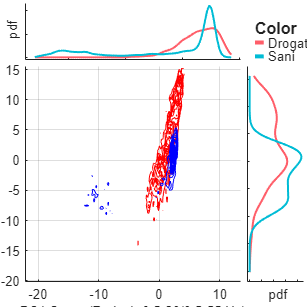

g.export('file_name', 'plot_finale', 'export_path','C:\Users\m.barado\Desktop\Research_Track', 'file_type','pdf'  );

**Overview of the Analysis Pipeline**

In this work, a data-driven pipeline was developed to characterize the dynamics of global brain states from multichannel local field potential (LFP) recordings, inspired by state-mapping approaches used to study the wake–sleep cycle. LFP signals were segmented into sliding time windows and analyzed in the frequency domain to extract two spectral power ratios sensitive to slow and low-frequency oscillatory activity. For each ratio, dimensionality across channels was reduced using principal component analysis (PCA), and the first principal component was taken as a global descriptor of cortical activity. The first components of the two ratios define a two-dimensional state space, in which each point represents the instantaneous brain state. This framework was extended to a group-level analysis by aggregating multiple recordings, enabling a direct comparison between natural sleep and ketamine-induced states. The resulting state-space representation provides a compact and continuous description of brain-state distributions and transitions across physiological and pharmacological conditions.

**Comparative Analysis of Brain States: Effects of Ketamine vs. Natural Sleep**

The density curves shown on the plot margins represent the distribution of PC1 scores along each axis for the two groups analyzed. In the case of natural sleep, the distribution is more compact and concentrated in a specific area of the state space, indicating greater coherence and stability of brain states. In contrast, the ketamine group shows a wider and shifted distribution, with densities spread differently, suggesting an altered brain state.

Looking at the two-dimensional plane, the points associated with natural sleep (in blue) cluster in a well-defined and confined region, while those in the ketamine group (in red) occupy a broader, shifted, and less uniform area. This difference indicates that ketamine modifies the dynamics of brain oscillations, producing more variable and less organized states compared to natural sleep.

From a physiological perspective, the increased spread and different position of states in the ketamine group reflect changes in the relative power of the frequency bands involved, such as an increase or decrease in low or mid-frequency bands. These changes may be associated with alterations in neuronal synchronization and functional coherence across different brain areas, thereby affecting the normal functioning of circuits involved in sleep and wakefulness.